# Motivation

The goal of science is to describe, predict, and understand natural phenomena based on observation and evidence. It just so turns out that the governing laws of the universe can be represented as partial differential equations (PDES). A PDE is a multi-variable function which depends on partial derivatives, often varying with space and time derivatives. In a less technical description, solving a PDE would provide information about the previous, current, and future state of a system, given some initial conditions and constraints. Foundational principles of engineering and physics are based on PDEs with applications in fluid dynamics, thermodynamics, electrodynamics, general relativity, and quantum mechanics. The widespread nature of solving PDEs has also given rise to a vast number of solution methods. The focus of this teaching module is on using finite difference methods (FDM) to solve PDES. Before delving into the subject matter, we should introduce the many sources of numerical errors that can occur during computing. As powerful as the computer has become, its accuracy is only finite, and each computation leads to the accumulation of small errors. Knowledge of their source is imperative before solving PDEs. This will allow you to differentiate between possible sources of error when using numerical methods. 

## Learning objectives

- Understand the basic sources of error during computing

## Prerequisites

- Calculus

- Basic understanding of ordinary and partial differential equations

## Introduction

To begin, let's discuss a very brief history of everything computing. Modern numerical analysis is often attributed to the publication of "Numerical Inverting of Matrices of High Order" in 1947 by John von Neumann and Herman Goldstine. However, numerical techniques have existed long before. Some of the first included root finding methods, and calculating lengths, areas, and volumes much like integral approximations. This was the precursor to calculus which eventually led to physical mathematical models. Finite difference methods were not conceived until 1715 by Brook Taylor nor widely used until the modern era. As you will see, the technique is tedious by hand, but is very powerful. Its usefulness changed with the birth of the computer, and since then continuous technological improvements have led to the development of high performance computers, which are now capable of utilizing these techniques at a level never before seen.

**Performance development of HPC over the last 20 years**

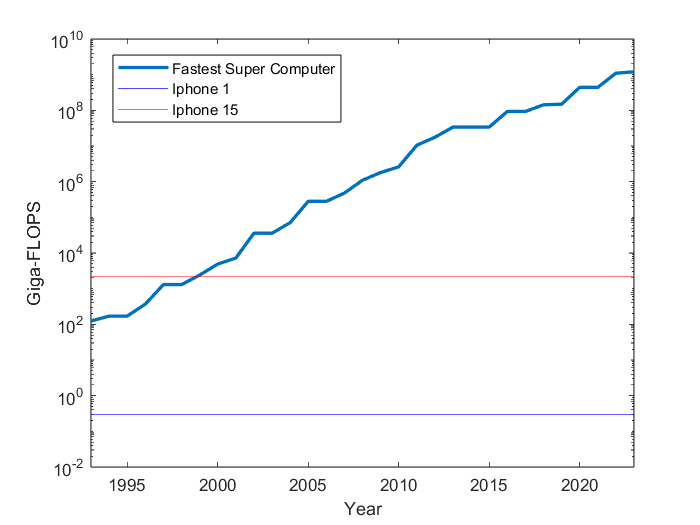

In the above figure, the floating-point operations per second (FLOPS) follows a linear trend year over year. In blue is the Giga-FLOPS the fastest super compuer each year was capabale of achieving. In the year 2002, a supercomputer was about as powerful as a modern-day laptop and now an Iphone 15, which fits in our pocket, is just as powerful. We have have a supercomputer from years past at our fingertips for performing high speed calculations. With computers as powerful as they are today, it is more important than ever to have a basic understanding of how their underlying calculations are performed. This is especially relevant when using numerical methods to solve PDEs.

## **Numerical errors**

Floating point storage lets you store very large and very small numbers compactly, with the trade-off that some operations won’t produce an exact result. The formula was developed in 1914 and is known as floating point arithmetic, with the most used being single and double precision. In double precision format, a floating-point number is made up of a 64 bit register, containing 1 sign, 11 exponent and 52 mantissa bits. This register approximates all numbers calculated by a computer where a bit is either 1 or 0. The following figure is an example of this register:

**64 Bit format**

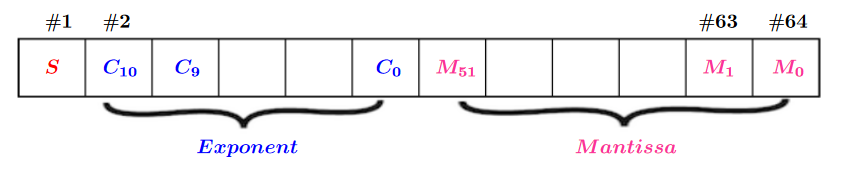

Mathematically, a floating point number $r$, can be specified with the following expression:


$$r =(-1)^s 2^{C-1023}(1+M)$$



$$C = \sum^{10}_{n=0} C_n2^n$$



$$M = \sum^{51}_{n=0} \frac{M_n}{2^{53-n}}$$


with the exponent equal to $C$ and the mantissa equal to $M$. As an example, let's use this formulaic expression to determine the smallest and largest possible numbers.

### **Realmin**

The smallest possible normalized number will only contain a single 1 in the exponent bit $C_0$:

**64-Bit format for realmin**


$$C = \sum_{n=0}^{10}C_n2^n = C_02^0 + C_12^1 + C_2 2^2 + ... = 1$$



$$M = \sum^{51}_{n=0} \frac{M_n}{2^{53-n}} = \frac{M_0}{2^{52-0}} + \frac{M_1}{2^{52-1}}  + \frac{M_2}{2^{52-2}} + ... = \frac{1}{2^{52}}$$



$$r = (-1)^0 2^{1-1023} = 2.2251 \times 10^{-308}$$


Push this button to see the realmin in MATLAB:

 
realmin

ans = 2.2251e-308

### **Realmax**

The largest possible number will contain all ones, filling all bits, except for $C_0$, because the largest possible $C = 2046$.

**64-Bit format for realmax**

userInput = 1e05;
if (userInput == 1.79769e308)
    disp("Correct")
elseif (userInput > 1.79769e308)
    disp("Overflow! Your answer is greater than the largest possible value.")
else
    disp("Not quite! Your answer is less than the realmax.")
end

Not quite! Your answer is less than the realmax.


### **Round off error**

In single and double precision systems, the precision limits are respectively $10^{-8}$ and $10^{-16}$; this is known as machine precision epsilon. It is the upper bound of error due to rounding numbers. In other words, epsilon determines how many significant digits can be accounted for during any computation. As we found out, numbers cannot be represented exactly, and irrational numbers can only be represented by the first 16 digits in double precision. You may think that 16 decimal places is quite a lot; however computers are often used to perform millions of calculations, and these small round off errors add up. The following equation should equal zero, but because of roundoff, it does not. How large do you think the errors will be for single and double precision?


$$\text{Error} = |\frac{k}{10} - \sum_{i=0}^k0.1 |$$


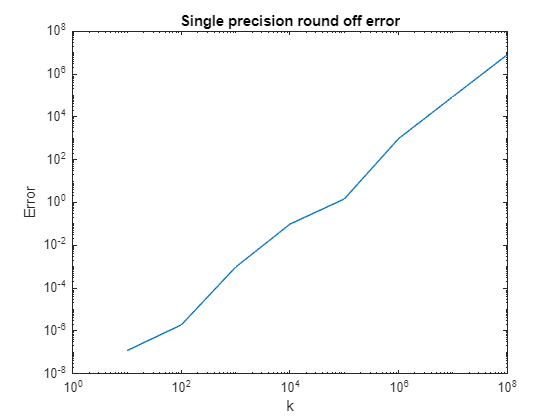

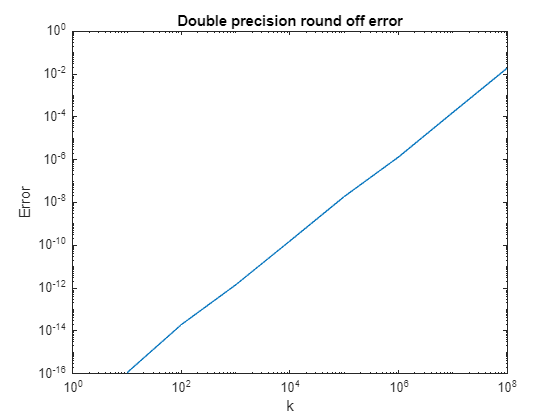

 

drawRoundOffError ()

As you can see, there are significant errors which build up using a 32-bit single precision register compared to a 64-bit double precision register. As a result, in almost all scientific computing applications, double precision is the most widely used. Even though greater precision can be obtained from quadruple and octuple precision, the trade-offs are too extreme. Higher levels of precision require more memory. Double precision offers a good balance giving us an error of less than 1, after $10^8$ summations. 

### Machine precision

Machine precision is the upper bound of relative error when approximating a number using the floating-point arithmetic system. In MATLAB, machine precision can be found using the function eps. It also takes on an argument such that eps(x) will return the positive distance from abs(x) to the next larger floating-point number of the same precision as x. 

eps

ans = 2.2204e-16

### **Loss of significance**

Also known as catastrophic cancellation, it occurs when an operation on two numbers increases the relative error substantially more than epsilon. As an example, consider the following calculation:


$$x = 0.1234567891234567890 \\
x_f = 0.1234567891$$


Here, $x$ is a number inputted into a machine, and $x_f$ is the floating point representation of that number with 10 digits of precision.


$$x - 0.1234567890 = 1.23456789 \times 10^{-10}\\
x_f - 0.1234567890 = 1.0 \times 10^{-10}$$


The first answer is accurate to 10 significant digits. The same operation using the floating point representation of the number yields only one significant digit. As a result, the second calculation amounts to a loss of significance. This type of error is often difficult to detect because it occurs unknowingly. 

**Next section**

The next teaching module covers solving parabolic partial differential equations. It includes learning about deriving finite difference schemes, local truncation error analysis, stability, and determining if a scheme is converging to the exact solution. The following link will bring you to the next module in this course.

open("parabolicEquations.mlx")

Error using open (line 85)
File 'parabolicEquations.mlx' not found.

## References

An overview of high performance computing and future requirements, Jack Dongarra, Oak Ridge National Laboratory

**Helper Functions**

function drawRoundOffError ()
    k = 10^8;
    rS = zeros(1, k);
    rD = zeros(1, k);
    
    total = 0.0;
    for i=1:k
        total = total + 0.1;
        rD(i) = abs (i/10 - total);
    end
    
    total = 0.0;
    total_s = single(total);
    for i=1:k
        total_s = single(total_s) + single(0.1);
        rS(i) = abs (single(i/10) - total_s);
    end  
    
    x = logspace (0, 8, 9);
    rSingle = [rS(1) rS(10), rS(100), rS(1000), rS(10^4), rS(10^5), rS(10^6), rS(10^7), rS(10^8)];
    rDouble = [rD(1) rD(10), rD(100), rD(1000), rD(10^4), rD(10^5), rD(10^6), rD(10^7), rD(10^8)];

    figure;
    loglog (x, rSingle);
    title ("Single precision round off error");
    xlabel ("k");
    ylabel ("Error");
    hold off;

    figure;
    loglog (x, rDouble);
    title ("Double precision round off error");
    xlabel ("k");
    ylabel ("Error");
end